# Sessió 10

Adem Ait

David Agut

## 1. App Classification Learner

L’objectiu d’aquesta pràctica és aprendre a classificar mostresa partir dels seus vectors de caracterìstiques. Usarem la App Classification learner de Matlab. Trobareu la informació necessària a:

https://uk.mathworks.com/help/stats/train-decision-trees-in-classification-learner-app.html

https://uk.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html

Podeu utilitzar el dataset Fisher iris (tot un clàssic) i experimentar amb diferents classificadors. En acabar heu de ser capaços de:

- Tunnejar correctament els paràmetres d’un classificador

- Probar diferents classificadors i escollir-ne els que donin millors resultats

- Fer experiments amb rigor (p.ex: cross-validation)

- Presentar els resultats de forma correcta ( corba RoC, matriu de confusió...)

## 2. Classificació automàtica d’espècies arbòries

**Un cop domineu la app Clasification learner, es planteja un problema de classificació amb imatges reals. Dins la tasca corresponent a la sessió 10 a Atenea, trobareu imatges de fulles de roure, faig i plàtan. Entreneu varios classificadors per aquestes tres espècies usant com a vectors de característiques els seus descriptors de Fourier.**

Hem fet servir la variable de tipus table: https://es.mathworks.com/help/matlab/ref/table.html#d120e80740

clear all
N=1000;
vartypes = strings([1,N+1]);
vartypes{N+1} = 'string';
vartypes(1:N) = 'double';
T = table('Size',[48 N+1],'VariableTypes',vartypes);
matriu = zeros(48,N+1);
for i = 1:16
    if i < 10
        nameErable = "l2nr00";
        nameFaig = "l15nr00";
        nameRoure = "l4nr00";
    else
        nameErable = "l2nr0";
        nameFaig = "l15nr0";
        nameRoure = "l4nr0";
    end
    it = string(i);
    Erable = imread('Erable\' + nameErable + it + '.jpg');
    Faig = imread('Faig\' + nameFaig + it + '.jpg');
    Roure = imread('Roure\' + nameRoure + it + '.jpg');
    
    for j=1:3  
        if (j == 1)
            im = Erable;
        end
        if (j == 2)
            im = Faig;
        end
        if (j == 3)
            im = Roure;
        end
        
        bw = im2bw(im,0.6);
        bw = ~bw;
        ee = strel('disk',5);
        bw = imclose(bw,ee);
        bw = imopen(bw,ee);
    
        ero=imerode(bw,strel('disk',1));
        cont=xor(ero,bw);
        
        % obtenim les coordenades del contorn
        [fila col] = find(bw,1); % Busquem el primer píxel
        B = bwtraceboundary(bw,[fila col],'E'); %direccio est a l'atzar
        % B conté les coordenades
        % Ho comprovem mostrant el resultat
        aux=zeros(size(bw));
        aux(sub2ind(size(aux),B(:,1),B(:,2)))=1;
        
        % centrem coordenades
        mig=mean(B);
        B(:,1)=B(:,1)-mig(1);
        B(:,2)=B(:,2)-mig(2);
        % Convertim les coordenades a complexes
        s= B(:,1) + i*B(:,2);
        % Cal que la dimensio del vector sigui parell
        [mida bobo]=size(B);
        if(mida/2~=round(mida/2))
         s(end+1,:)=s(end,:); %dupliquem l'ultim
         mida=mida+1;
        end
        % Calculem la Fast Fourier Transform
        z=fft(s);
        
        %% Reduim la quantitat de descriptors de Fourier
%         N=1000; % agafem N descriptors
        tmp=z;
        tmp(N+1:end-N)=0; % eliminem els del mig perque es duplica l'espectre
        tmp2 = zeros(N,1);
        tmp2(1:N) = tmp(1:N);
        % Tornem al pla 
        ss2=abs(ifft(tmp2));
        ss2=ss2';
        
        if (j == 1)
            T{i,1:N} = ss2(1:N);
            T.Var1001(i) = 'Erable';
        end
        if (j == 2)
            T{i+16,1:N} = ss2(1:N);
            T.Var1001(i+16) = 'Faig';
        end
        if (j == 3)
            T{i+32,1:N} = ss2(1:N);
            T.Var1001(i+32) = 'Roure';
        end
    end
end

**Es demana un informe (en pdf) que inclogui el codi usat per a obtenir els descriptors, la descripció dels experiments realitzats, els classificadors que han funcionat millor i els resultats obtinguts. Indiqueu quines caracaterístiques del vector són necessàries per a la correcta classificació, i  quines no són significatives.**

Primer hem provat amb 1000 descriptors, i en el millor dels casos ens donava un 77% d'encert. Hem pensat que potser 1000 descriptors eren més dels necessaris per obtenir un bon resultat. Després hem baixat el nombre de descriptors a 50. El resultat s'ha mantingut, un 77% d'encert. Aleshores hem usat PCA, limitant el nombre de components numèrics a 50 i la variança al 95%, usant 100 descriptors. Això ens ha donat millors resultat, un 85% d'encert. També hem provat amb 30 components numèrics usant 200 descriptors, amb un resultat millor: 87,5%.

Hem usat PCA per així de cara a la pràctica 2 anar amb més experiència. El PCA s'utilitza per reduir característiques que no ens aporten informació molt relevant en comparació amb altres.

A la següent imatge es veu el primer *scatter plot* de les primeres dos variables, treballant amb 50 descriptors: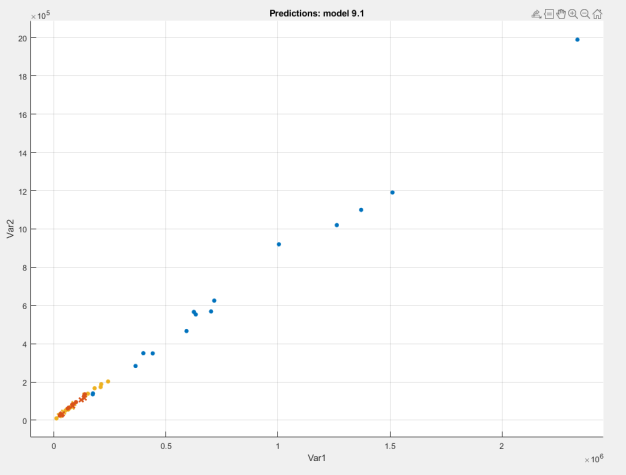

Una altra manera de comprovar millors resultats és fent ús del feature selection. Enlloc d'anar seleccionant o no features aleatoriament hem buscat una funció que ens retorna un ranking de les features més relevants.

(https://es.mathworks.com/help/stats/fscchi2.html)

Ho hem fet amb 50 descriptors per tant la crida és la següent:

idx = fscchi2(T,'Var51');

Gràcies a aquesta funció hem obtingut un ranking de les característiques del vector més rellevants, ordenades segons l'índex. Amb aquesta informació hem anat al final del ranking i hem anat desactivant del classification learner les característiques que sortien, ja que volia dir que aquestes no eren gaire rellevants i per tant no ajudaven en la classificació. Hem anat desactivant-les fins que ens hem quedat amb només 10 features, on obteníem una precisió del 87,5% amb el Cubic SVM.

Amb 50 features hem vist que les 10 necessàries i més relevants per obtenir bons resultats eren (en aquest ordre):  36    35    30    44    16    3    23    2    7    47. I  les 10 que eren menys relevants i que, per tant, aportaven menys informació eren (de més a menys relevant): 8    24    46    40    39    42    20    41    27    28    33

El classificador que ens ha donat millor resultat ha sigut el Cubic SVM. També ens han donat bastant bon resultats els Fine, Coarse i Medium tree, tot i que a mesura que augmentàvem el número de features el seu rendiment baixava en picat. El Fine KNN i  el Ensemble (subspace KNN) donaven millors resultats que el Cubic SVM quan teníem molts features, però a mesura que hem anat desactivant-ne, el Cubic SVM ha acabat obtenint millors resultats. Aquest canvi de rendiment s'ha produït quan hem arribat a 20-25 features.

A continuació mostrem diferents resultats: